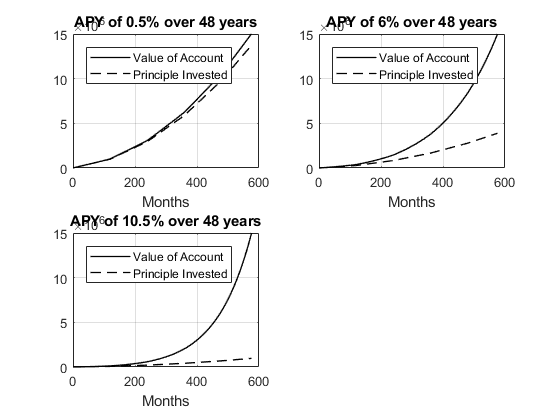

% Part 2
u  = @(n) 1.0 .* (n >= 0) .* (mod(n, 1) == 0);
k = 1 + i ./ 12;
y_m = @(n,m,k) (k .^ (n+1-m) - 1) .* u(n-m);
i = [0.005, 0.06, 0.105];
m = 12 * 48;

C = zeros(3,1);
P = zeros(3,1);
y = zeros(3,2);
fn_y = @(n,i,C,D) (12 * C / i) .* (1 + i/12).^(n+1);


for v = 1:1:3
    % Figure out monthly payments
    C(v) = i(v) .* 15E6 ./ (12 .* (y_m(m,0,k(v)) - y_m(m,120,k(v)) + 2.*y_m(m,120,k(v)) - 2.*y_m(m,240,k(v)) + 3.*y_m(m,240,k(v)) - 3.*y_m(m,360,k(v))...
    + 4.*y_m(m,360,k(v)) - 4.*y_m(m,480,k(v)) + 5.*y_m(m,480,k(v)) - 5.*y_m(m,576,k(v))));  
    
    % Check that these payments make sense recursively
    y_t = zeros(m+1,1);
    P_t = zeros(m+1,1);
    for l = 0:1:(m-1)
        y(v,1) = (1+i(v)/12) * y(v,1) + C(v)*((u(l)-u(l-120)) + 2*(u(l-120)-u(l-240)) + 3*(u(l-240)-u(l-360)) + 4*(u(l-360)-u(l-480)) + 5*(u(l-480)-u(l-576)));
        y_t(l+1) = y(v,1);
        P_t(l+1) = C(v) .* ((u(l)-u(l-120)) + 2.*(u(l-120)-u(l-240)) + 3.*(u(l-240)-u(l-360)) + 4.*(u(l-360)-u(l-480)) + 5.*(u(l-480)-u(l-576))) + P_t(l + 1 * u(-l));
    end
    y(v,1) = (1+i(v)/12) * y(v,1);
    y_t(m+1) = y(v,1);
    P_t(m+1) = P_t(m);
    
    % Check that our solution matches
    y(v,2) = (12 .* C(v) .* (y_m(m,0,k(v)) - y_m(m,120,k(v)) + 2.*y_m(m,120,k(v)) - 2.*y_m(m,240,k(v)) + 3.*y_m(m,240,k(v)) - 3.*y_m(m,360,k(v)) + 4.*y_m(m,360,k(v)) - 4.*y_m(m,480,k(v)) ...
           + 5.*y_m(m,480,k(v)) - 5.*y_m(m,576,k(v)))) ./ i(v);
     
         
    % Calculate principle
    P(v) = 12 * C(v) * (10 * (1 + 2 + 3 + 4) + 8  * 5);
     
    % Plot the value of the retirement account as a function of month over the investment interval.
    n = 0:1:m;
    subplot(2,2,v);
    plot(n, y_t, '-', n, P_t, '--', 'color', [0,0,0], 'linewidth', 1);
    ylim([0 1.5E7]);
    xlabel('Months');
    %ylabel("Value of Account");
    title("APY of " + string(i(v)*100)+"% over 48 years");
    grid on;
    legend('Value of Account', 'Principle Invested', 'Location','northwest');
end

C

C =    1.0e+03 *

    8.1603
    2.3103
    0.5737


C_s = strings(3,1);
for i=1:3
    C_s(i) = num2bank(C(i));
end
C_s

C_s = 3×1 string array
    "8,160.3"
    "2,310.26"
    "573.69"


y

y =    1.0e+07 *

    1.5000    1.5000
    1.5000    1.5000
    1.5000    1.5000


P

P =    1.0e+07 *

    1.3709
    0.3881
    0.0964


P_s = strings(3,1);
for i=1:3
        P_s(i) = num2bank(P(i));
end
P_s

P_s = 3×1 string array
    "13,709,317.1"
    "3,881,251.91"
    "963,814.65"
